# Test CNN2D optimization, training and Testing

# Retraining the whole model for a new Sensor

## Load the Szenario or build from scratch

clearvars;
%LoadToolbox
addPaths;

%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

% If multiple Sensors should be used for initial model building
%loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat']);convertCharsToStrings([locationData 'sensorB.mat'])];
%loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat']);convertCharsToStrings([locationData 'target.mat'])];

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 1;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Not the exact split is performed than in the original data (~20 UGMs less in test Set)
[data,target] = loadDataFull(loadStruct);

Data\sensorA.mat
acetone
Split
RandomFlag
   0



%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorB.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 2;

%Specific for Method 2 defines the number of transfer UGMs
loadStruct.transf = 25;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Same 20 % in Testdata 25 transfer UGMs
[dataRetrainB,targetRetrainB] = loadDataFull(loadStruct);

Data\sensorB.mat
acetone
Transfer
RandomFlag
   0



%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorC.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 2;

%Specific for Method 2 defines the number of transfer UGMs
loadStruct.transf = 25;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Same 20 % in Testdata 25 transfer UGMs
[dataRetrainC,targetRetrainC] = loadDataFull(loadStruct);

Data\sensorC.mat
acetone
Transfer
RandomFlag
   0



## If alredy Optimized -> Train and Test TCOCNN

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams_retrain.mat'];
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression);

No Model Built


|==============================================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     n_filter | SectionDepth | InitialLearn-|       stride |       kernel |   numNeurons |      dropOut | InitialLearn-|    MaxEpochs |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | Rate_Beginni |              |              |              |              | Rate         |              |
|==============================================================================================================================================================================================================|
|    1 | Best   |      42.249 |      357.83 |      42.249 |      42.249 |          136 |            5 |   0.00015723 |           31 |           75 |          827 | 

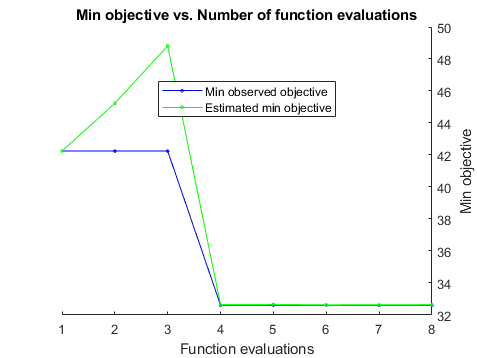


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 8 reached.
Total function evaluations: 8
Total elapsed time: 2279.588 seconds
Total objective function evaluation time: 2277.6201

Best observed feasible point:
    n_filter    SectionDepth    InitialLearnRate_Beginning    stride    kernel    numNeurons    dropOut    InitialLearnRate    MaxEpochs
    ________    ____________    __________________________    ______    ______    __________    _______    ________________    _________

       65            4                  0.00087536              29        68         908        0.47987       0.00048548          78    

Observed 


%Fill dataRetrain
data.retrain = dataRetrainB.train;
data.retrainVal = dataRetrainB.test;

target.retrain = targetRetrainB.train;
target.retrainVal = targetRetrainB.test;

%With already optimized variables start training directly
tcocnnTest2.optimizeTCOCNNRetrain(paraStore,data,target,8);

%Train TCOCNN on sensor A
tcocnnTest2.train(data.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(data.test);
disp(helpers.RMSE.loss(pred,target.test));

   15.9977



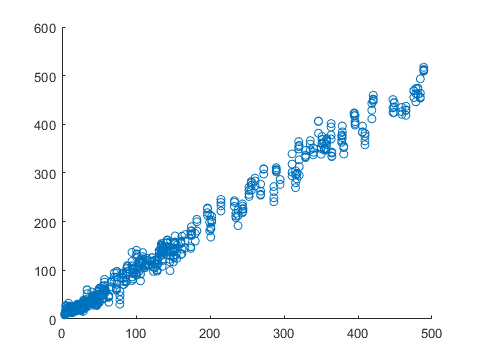


%display target vs pred
figure()
scatter(target.test,pred)

## Test on new Sensor

%Predict Test Data from newSensor
pred = tcocnnTest2.apply(dataRetrainC.test);
disp(helpers.RMSE.loss(pred,targetRetrainC.test));

  180.0831



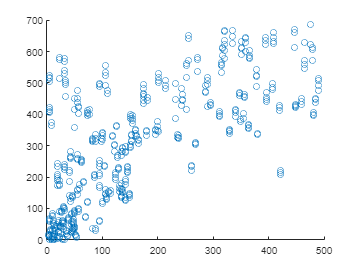


%display target vs pred
figure()
scatter(targetRetrainC.test,pred)

## Retrain the model

tcocnnTest2_Retrain = copy(tcocnnTest2);
load(paraStore)
tcocnnTest2_Retrain.retrainFull(dataRetrainC.train,targetRetrainC.train,optim);

%Predict Test Data from newSensor
pred = tcocnnTest2_Retrain.apply(dataRetrainC.test);
disp(helpers.RMSE.loss(pred,targetRetrainC.test));

   83.1086



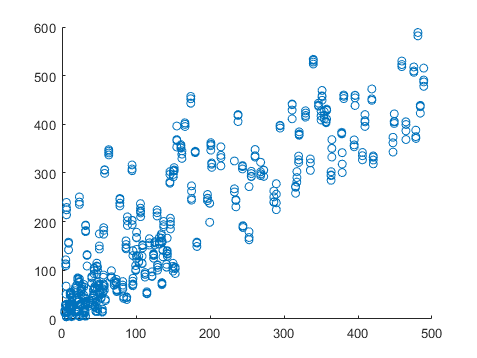


%display target vs pred
figure()
scatter(targetRetrainC.test,pred)